# ASTE 583 - Homework 1

## Problem 1

x = [-1, 0, 2, 3, 5];
y = [-1, 2, 9, 10, 14];
m = length(x);

Using the given normal equations:

(A) $\left(\sum_{i=1}^mx_i^2\right)\alpha + \left(\sum^m_{i=1}x_i\right)\beta = \sum^m_{i=1}x_iy_i$

(B) $\left(\sum^m_{i=1}x_i\right)t\alpha + m\beta = \sum^m_{i=1}y_i$

sol = linsolve([sum(x.^2), sum(x);sum(x), m],[sum(x.*y); sum(y)]);

alpha = sol(1)

alpha = 2.5351

beta = sol(2)

beta = 2.2368

### (a) y = 2.5351x + 2.2368

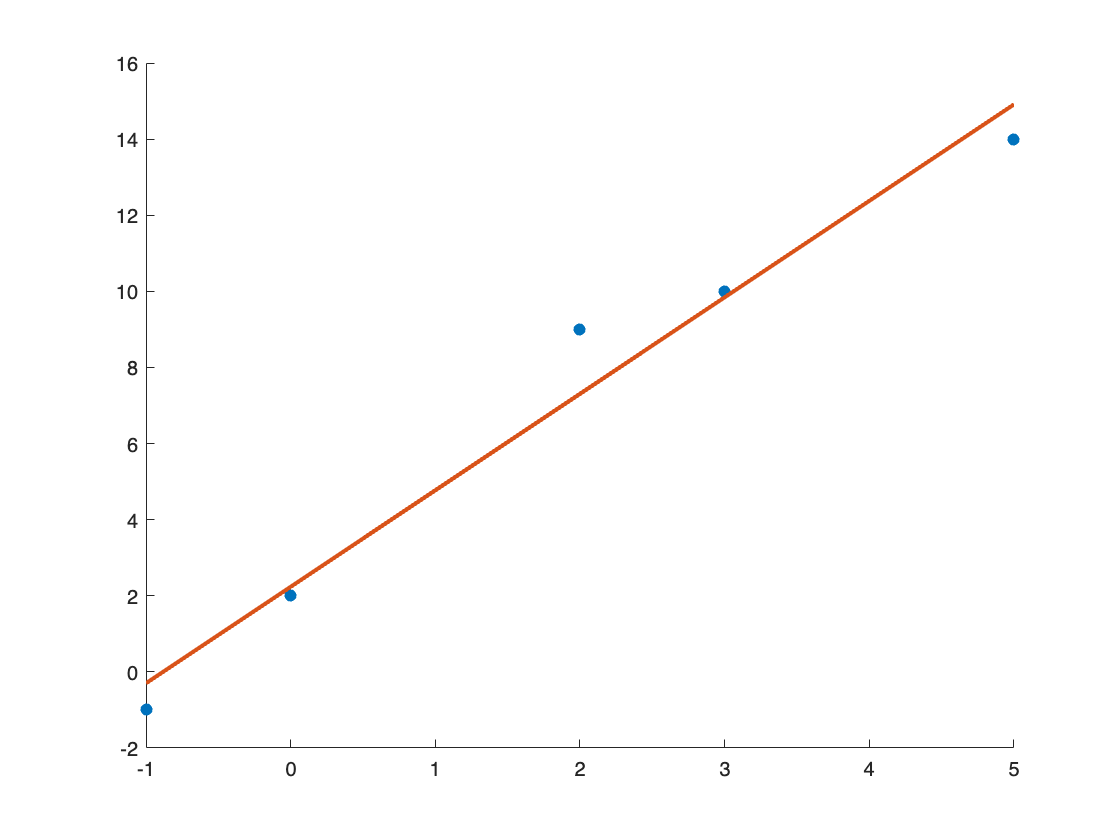

f = @(x) alpha*x + beta;
fig = figure();
hold on
scatter(x,y,'filled')
plot(x,f(x),"LineWidth",2)
hold off

### (b) See above graph

r = y - f(x)

r =    -0.7018   -0.2368    1.6930    0.1579   -0.9123


### (c) $\matrix{ \text{x} & \text{y} & \text{r} \cr -1 & -1 & -0.7018 \cr 0 & 2 & -0.2368 \cr 2 & 9 & 1.6930 \cr 3 & 10 & 0.1579 \cr 5 & 14 & -0.9123}$

sum(r)

ans = 8.8818e-16

### (d) The sum of the residuals is approximately zero

sum(r.^2)/m

ans = 0.8544

### (e) The average squared error is 0.8544

## Problem 2


$$J = \sum^m_{i=1}(\eta_i - A\zeta^3_i - B)^2$$



$$\frac{\partial J}{\partial A} = \sum^m_{i=1}2\left(\eta_i - A\zeta^3_i - B\right)\left(-\zeta^3_i\right)=0 \Rightarrow \left(\sum^m_{i=1}\zeta^6_i\right)A+\left(\sum^m_{i=1}\zeta^3_i\right)B = \sum^m_{i=1}\eta_i\zeta^3_i$$



$$\frac{\partial J}{\partial B} = \sum^m_{i=1}2\left(\eta_i - A\zeta^3_i - B \right)\left(-1\right) = 0 \Rightarrow \left(\sum^m_{i=1}\zeta^3_i\right)A + mB = \sum^m_{i=1}\eta_i$$


### (a) The normal equations are: $\left(\sum^m_{i=1}\zeta^6_i\right)A+\left(\sum^m_{i=1}\zeta^3_i\right)B = \sum^m_{i=1}\eta_i\zeta^3_i$ and $\left(\sum^m_{i=1}\zeta^3_i\right)A + mB = \sum^m_{i=1}\eta_i$

zeta = [1, 2, 3];
eta = [1, 9, 25];
m = 3;
sol = linsolve([sum(zeta.^6), sum(zeta.^3); sum(zeta.^3), m],[sum(eta.*zeta.^3); sum(eta)]);
A = sol(1)

A = 0.9061

B = sol(2)

B = 0.7937

### (b) $\eta = 0.9061\zeta^3 + 0.7937$

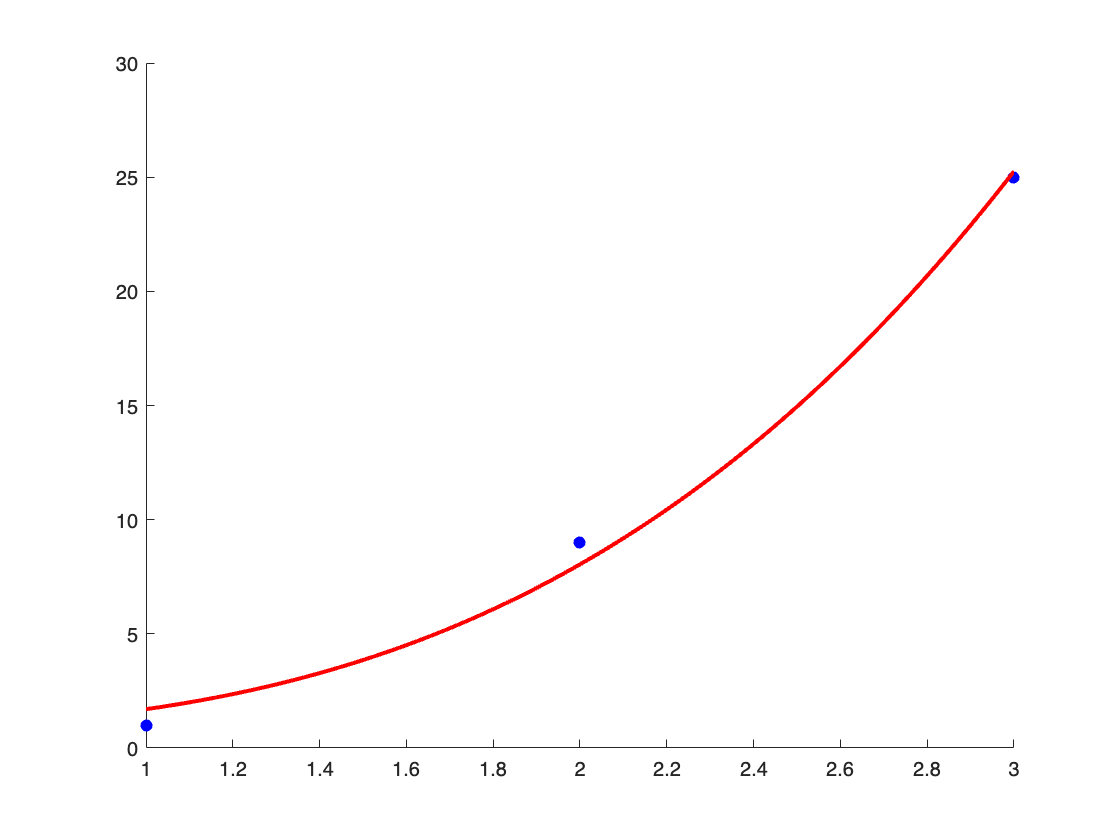

f = @(zeta) A*zeta.^3 + B;
fig = figure();
hold on
scatter(zeta,eta,'blue','filled')
zeta = linspace(zeta(1),zeta(m));
plot(zeta,f(zeta),'Color','Red','LineWidth',2)
hold off

## Problem 3


$$\rho = (t^2 - 2)\alpha + 2t\beta$$



$$J = \sum_{i=1}^m\left(\rho_i - \left(t_i^2 - 2\right)\alpha - 2t_i\beta \right)^2$$



$$\frac{\partial J}{\partial \alpha} = \sum_{i=1}^m2\left(\rho_i - \left(t_i^2 - 2\right)\alpha - 2t_i\beta \right) \left(t_i^2 - 2\right) = 0 \Rightarrow \left(\sum_{i=1}^m\left(t_i^2 - 2\right)^2\right)\alpha + \left(\sum_{i=1}^m\left(2t_i^3 - 4t_i\right)\right)\beta = \sum_{i=1}^m\rho_i\left(t_i^2 - 2\right)$$



$$\frac{\partial J}{\partial \beta} = \sum_{i=1}^m2\left(\rho_i - \left(t_i^2 - 2\right)\alpha - 2t_i\beta \right)\left(-2t_i\right) = 0 \Rightarrow \left(\sum_{i=1}^m t_i^3 - 2t_i\right)\alpha + \left(\sum_{i=1}^m2t_i^2\right)\beta = \sum_{i=1}^m\rho_it_i$$


t = [1, 2, 3, 4, 5];
rho = [-3, 3, 6, 15, 22];
m = 5;
sol = linsolve([sum((t.^2 - 2).^2), sum(2.*t.^3 - 4.*t); sum(t.^3 - 2.*t), sum(2.*t.^2)],[sum(rho.*(t.^2 - 2)); sum(rho.*t)]);
alpha = sol(1);
beta = sol(2);
M0 = beta

M0 = -0.0805

B0 = -2*alpha

B0 = -2.0498


$$\rho = 1.0249\left(t^2 - 2\right) - 0.0805\left(2t\right)$$


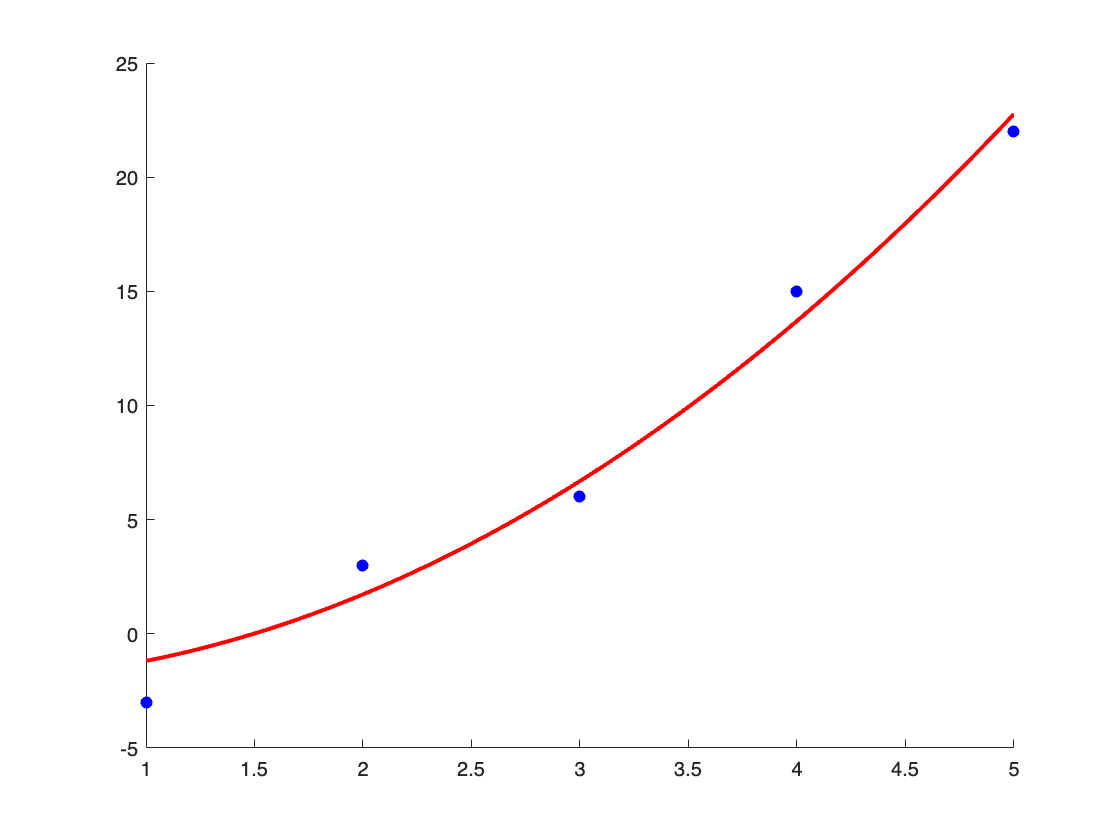

f = @(t) alpha*(t.^2 - 2) + 2*t*beta;
fig = figure();
hold on
scatter(t, rho, 'blue', 'filled')
t = linspace(t(1),t(m));
plot(t,f(t),'Color','red','LineWidth',2)
hold off

## Problem 4


$$\rho = 2tM_0 + \left(1 - \frac{t^2}{2}\right)B_0$$



$$\bar{x} = \left[ \matrix{M_0-\frac{t}{2}B_0 \cr tM_0 + B_0 }\right]$$
 
$$\bar{x}_0 = \left[ \matrix{M_0 \cr B_0} \right]$$


### (a) $\tilde{H} = \left[ \matrix{\frac{\partial \rho}{\partial M} & \frac{\partial \rho}{\partial B}} \right] = \left[ \matrix{t & 1} \right]$

### (b) $\Phi = \left[ \matrix{\frac{\partial M}{\partial M_0} & \frac{\partial M}{\partial B_0} \cr \frac{\partial B}{\partial M_0} & \frac{\partial B}{\partial B_0}} \right] = \left[ \matrix{1 & -\frac{t}{2} \cr t & 1} \right]$

### (c) $H_i = \left[ \matrix{\frac{\partial \rho}{\partial M_0} & \frac{\partial \rho}{\partial B_0}} \right] = \left[ \matrix{2t & \left(1 - \frac{t^2}{2}\right)}\right]$


$$J = \sum_{i=1}^m\left(y_i - H_i \bar{x}_0\right)^2$$



$$\frac{\partial J}{\partial \bar{x}_0} = \sum_{i=1}^m2\left(y_i - H_i\bar{x}_0\right)\left(H_i^T\right) = 0 \Rightarrow \sum_{i=1}^mH_i^TH_i\bar{x}_0=\sum_{i=0}^mH_i^Ty_i$$


### (d) $\bar{x}_0 = \left(H^TH\right)^{-1}\left(H^TY\right)$

t = [1, 2, 3, 4, 5];
y = [-3; 3; 6; 15; 22];

H = [];
for i=1:length(t)
    H = [H; 2*t(i) (1 - t(i)^2/2)];
end

x = inv(transpose(H)*H)*transpose(H)*y;
M0 = x(1)

M0 = -0.0805

B0 = x(2)

B0 = -2.0498

rho = @(t) 2*t*M0 + (1 - t.^2/2)*B0;
fig = figure();
hold on
scatter(t, y, 'blue', 'filled')
t = linspace(t(1),t(end));
plot(t,rho(t),'Color','red','LineWidth',2)
hold off